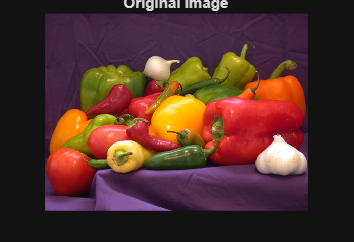

clc; clear; close all;

% Step 1: Read input image (color)
img = imread('peppers.png');   % MATLAB built-in color image
figure, imshow(img), title('Original Image');

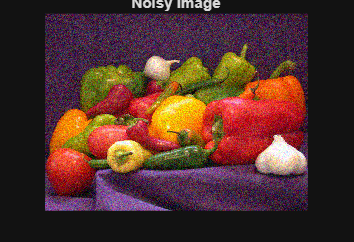


% Step 2: Add Gaussian noise (simulate wireless transmission)
noisy_img = imnoise(img, 'gaussian', 0, 0.01);
figure, imshow(noisy_img), title('Noisy Image');

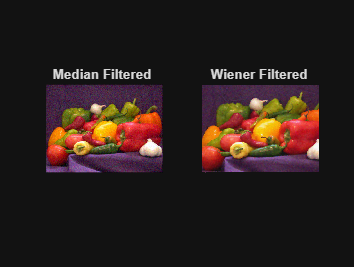


% Step 3: Apply filters
% Median filter works channel by channel for color images
median_filtered = img;
for i = 1:3
    median_filtered(:,:,i) = medfilt2(noisy_img(:,:,i), [3 3]);
end

wiener_filtered = img;
for i = 1:3
    wiener_filtered(:,:,i) = wiener2(noisy_img(:,:,i), [5 5]);
end

figure,
subplot(1,2,1), imshow(median_filtered), title('Median Filtered ');
subplot(1,2,2), imshow(wiener_filtered), title('Wiener Filtered ');


% Step 4: Performance Metrics (PSNR & SSIM for color)
psnr_noisy = psnr(noisy_img, img);
psnr_median = psnr(median_filtered, img);
psnr_wiener = psnr(wiener_filtered, img);

ssim_noisy = ssim(noisy_img, img);
ssim_median = ssim(median_filtered, img);
ssim_wiener = ssim(wiener_filtered, img);

disp('--- PSNR Results ---');

--- PSNR Results ---


disp(['Noisy Image: ', num2str(psnr_noisy)]);

Noisy Image: 20.4806


disp(['Median Filtered: ', num2str(psnr_median)]);

Median Filtered: 27.3027


disp(['Wiener Filtered: ', num2str(psnr_wiener)]);

Wiener Filtered: 29.3695



disp('--- SSIM Results ---');

--- SSIM Results ---


disp(['Noisy Image: ', num2str(ssim_noisy)]);

Noisy Image: 0.64836


disp(['Median Filtered: ', num2str(ssim_median)]);

Median Filtered: 0.88316


disp(['Wiener Filtered: ', num2str(ssim_wiener)]);

Wiener Filtered: 0.94204
